# Demo:  DM-RS Configuration in 5G NR

The demodulation reference signals (DM-RS) are the basic reference signals for channel estimation of the downlink data frames in the 5G NR standard.  We will use these symbols to illustrate the basic concepts of channel estimation in this unit.  In this demo, you will learn to:

- Configure the DM-RS signals with the MATLAB 5G Toolbox

- Visualize the location of the DM-RS and data symbols

- Compute overhead of the reference signals

We will address the channel estimation in the other demos and labs.

## Carrier Configuration

To illustrate the concepts, we look at a typical 10 MHz carrier.

fc = 2.3e9;              % Carrier frequency
SubcarrierSpacing = 15;  % SCS in kHZ
NRB = 52;                % number of resource blocks
numScPerRB = 12;         

% NR carrier config
carrierConfig = nrCarrierConfig(...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);

Before configuring the DM-RS, let's look at a simple channel so we can see the coherence time and bandwidth.

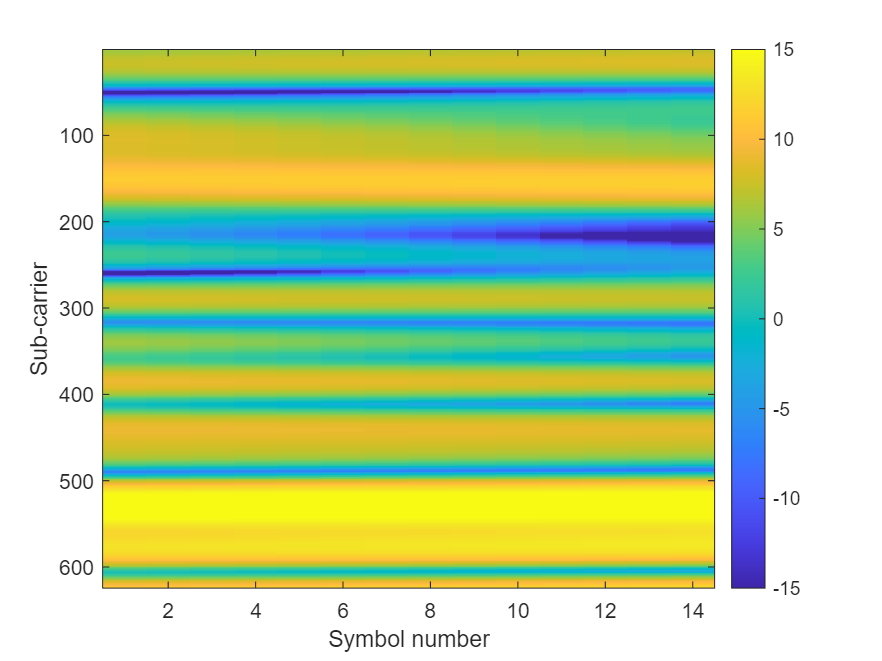

% Channel tap parameters
npaths = 20;       % number of paths
dlymean = 500e-9;  % mean delay spread in seconds
fdmax = 200;       % max Doppler spread in Hz

gain = zeros(npaths,1);
dly = exprnd(dlymean,npaths,1);
theta = unifrnd(-60,60,npaths,1);
fd = fdmax*cos(deg2rad(theta));

% Create the channel
EsN0Avg = 10;
fdchan = FDChan(carrierConfig, 'gain', gain, ...
    'fd', fd, 'dly', dly, 'EsN0Avg', EsN0Avg);

% Create the TX grid and populate with the CSI-RS symbols
numPorts = 1;
txGrid = nrResourceGrid(carrierConfig,numPorts);

% Run the TX grid through the channel
frameNum = 0;
slotNum = 0;
[rxGrid,chanGrid,noiseVar] = fdchan(txGrid, frameNum, slotNum);

% Compute the true channel SNR
snr = 10*log10(abs(chanGrid).^2/noiseVar);
clf;
imagesc(snr, [-15 15]);
colorbar();
xlabel('Symbol number');
ylabel('Sub-carrier');

## Configuring DM-RS and PDCCH

The 5G NR standard has a highly configurable DM-RS that can vary the density of the DM-RS in time and frequency.  This configuration can be selected on the basis of the coherence time and bandwidth.   This [website](https://www.sharetechnote.com/html/5G/5G_PDSCH_DMRS.html) has an excellent demonstration of the DM-RS configurations.

The MATLAB 5G Toolbox has a very nice data structure to represent the configurations.  In this case, we will use a simple configuration with 6 REs for DM-RS per RB.

% DM-RS config
dmrsConfig = nrPDSCHDMRSConfig(...
    'NumCDMGroupsWithoutData', 1, ...  % No unused DM-RS
    'DMRSAdditionalPosition', 0, ...   % No additional DM-RS in time
    'DMRSConfigurationType', 1);  % 1=6 DM-RS per sym,  2=4 per sym

Once the DM-RS is configured, we can then configure the PDSCH (the downlink data).  In this case, we also add the PT-RS (phase tracking reference signals).



% Configure the physical downlink shared channel parameters
pdschConfig = nrPDSCHConfig();
pdschConfig.NSizeBWP = [];   % Empty implies that the value is equal to NSizeGrid
pdschConfig.NStartBWP = [];  % Empty implies that the value is equal to NStartGrid
pdschConfig.PRBSet = (0:NRB-1);   % Allocate the complete carrier
pdschConfig.SymbolAllocation = [0 14]; % Symbol allocation [S L]
pdschConfig.MappingType = 'A'; % PDSCH mapping type ('A' or 'B')
pdschConfig.EnablePTRS = true;
pdschConfig.PTRS =  nrPDSCHPTRSConfig();
pdschConfig.DMRS = dmrsConfig;


We can get the indices and symbols for the different channels with the following commands.


% Get the PT-RS symbols and indices
ptrsSym = nrPDSCHPTRS(carrierConfig,pdschConfig);
ptrsInd = nrPDSCHPTRSIndices(carrierConfig,pdschConfig);

% PDSCH mapping
[pdschInd,info] = nrPDSCHIndices(carrierConfig,pdschConfig);

% PDSCH DM-RS precoding and mapping
dmrsSym = nrPDSCHDMRS(carrierConfig,pdschConfig);
dmrsInd = nrPDSCHDMRSIndices(carrierConfig,pdschConfig);


To visualize the mapping we create a grid and place and index of the channel used in each RE.  These can then be plotted.

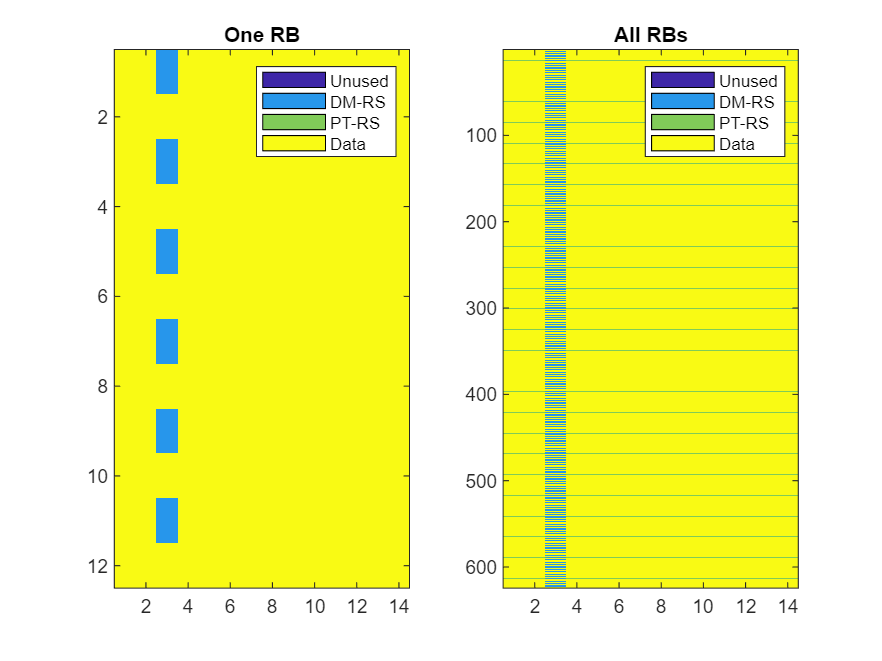

% Create the TX grid and populate with the CSI-RS symbols
numPorts = 1;
txGrid = nrResourceGrid(carrierConfig,numPorts);
txGrid(dmrsInd) = 1;
txGrid(ptrsInd) = 2;
txGrid(pdschInd) = 3;
chanNames = {'Unused', 'DM-RS', 'PT-RS', 'Data'};


subplot(1,2,1);
plotChan(txGrid(1:12,:), chanNames);
title('One RB');
subplot(1,2,2);
plotChan(txGrid, chanNames);
title('All RBs');

## In-Class Exercise

For each channel, find the fraction of the REs used by the channel.

% TODO

Roughly, estimate the number of DM-RS symbols per coherence BW

% TODO
